# Five Bar Robot

## Introduction

The five-bar planar parallel manipulatior is a typical parallel mechanism with 2DOF. It consists of 2 active joints, fixed on the base ($A_1$ and $A_2$), and 3 passive joints ($B_1$, $B_2$ and the end-effector $\mathrm{EE}$).

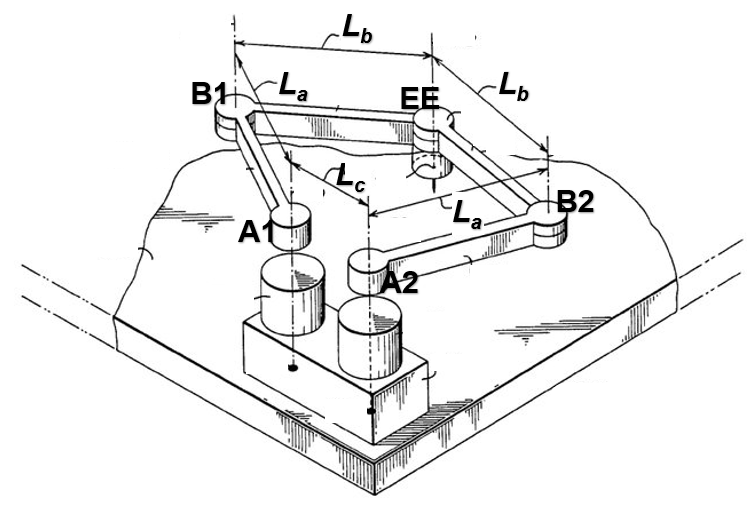

*Adapted from Bonev, Ilian. (2015). User's manual for the DexTAR five-bar parallel robot. 10.13140/RG.2.1.1368.4645. Link:https://www.researchgate.net/publication/277299749_User%27s_manual_for_the_DexTAR_five-bar_parallel_robot/figures*

A 2D Model created using freeCAD is displayed herebelow:

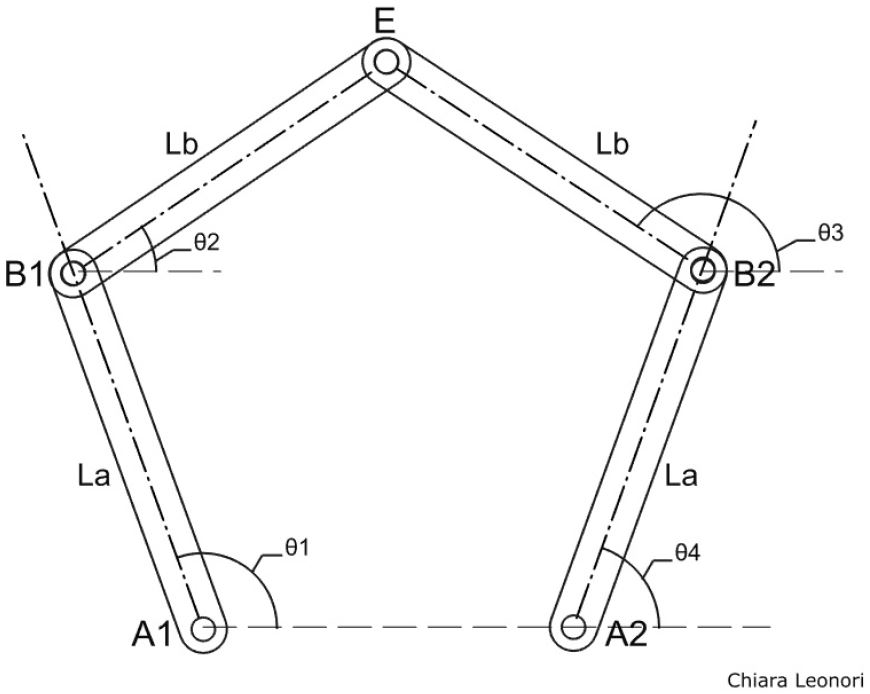

## Forward Kinematic

Taking $A_1$as origin $O$ of the reference system:


$$\pmatrix{x_{e} \cr y_{e}}
= 
\pmatrix{
L_a cos \theta_1 + L_b cos \theta_2 \cr
L_a sin \theta_1 + L_b sin \theta_2} = 
\pmatrix{
L_c + L_a cos \theta_4 + L_b cos \theta_3 \cr
L_a sin \theta_4 + L_b sin \theta_3}$$


As already mentioned, the joints **A **and **C** are not activated by the stepper motors, hence:

- $\theta_2 \;$and  $\theta_3$ are dependent,

- $\theta_1 \;$and  $\theta_4$ are independent and results to be the inputs of the controller for the parallel manipulator.

The dependent angles($\theta_2 ,\theta_3$) can be then computed dependending on the input angles ($\theta_1 ,\theta_4$).


$$\theta_2 =\sin^{-1} \left(\frac{L_b \;\sin \theta_3 +L_a \sin \theta_4 -L_a \;\sin \theta_1 }{L_b }\right)$$



$$\theta_3 =2\arctan \left(\frac{-F\pm \sqrt{E^2 +F^2 -C^2 }}{-B+C}\right)$$


where $\begin{array}{l}
E=2L_b \left(L_c +L_a \left(\cos \theta_4 -\cos \theta_1 \right)\right)\\
F=2L_a L_b \left(\sin \theta_4 -\sin \theta_1 \right)\\
G={L^2 }_c +2{L^2 }_a +{2L}_c L_a \cos \theta_4 -2L_c L_a \cos \theta_1 -2{L^2 }_a \cos \left(\theta_4 -\theta_1 \right)
\end{array}$

These two equations allow to determine the actuation angles in he manipulative system for specific coordinates of the end-effector.

## Inverse Kinematic

Knowing the coordinates of the end-effector at point $\mathrm{EE}\left(x_e ,y_e \right)$, the rotation angles of actuators can be calculated:


$$\left\lbrace \begin{array}{l}
\theta_1 =2\mathrm{atan}\left(\frac{-F_1 \pm \sqrt{\left(E_1^2 +F_1^2 -G_1^2 \right)}}{G_1 -E_1 }\right)\\
\theta_4 =2\mathrm{atan}\left(\frac{-F_4 \pm \sqrt{\left(E_4^2 +F_4^2 -G_4^2 \right)}}{G_4 -E_4 }\right)
\end{array}\right.$$


where     $\begin{array}{l}
E_1 =-2L_A x_{\mathrm{ee}} \\
F_1 =-2L_A y_{\mathrm{ee}} \\
G_1 =L_A^2 -L_B^2 +x_e^2 +y_e^2 
\end{array}$    and     $\begin{array}{l}
E_4 =2L_A \left({-x}_e +L_C \right)\\
F_4 =-2L_A y_e \\
G_4 =L_c^2 +{L^2 }_A -L_B^2 +x_e^2 +y_e^2 -2L_C x_e 
\end{array}$

From the equations that compute $\theta_1$and $\theta_4$can be seen that there are 4 possible solutions in total, describing the configurations of the Five-Bar system.

#### Configurations

The previous equations for $\theta_1$and $\theta_4$show that there are always foru solution for the inverse kinematic problem within the workspace:

$1\ldotp \;\left(\theta_1^+ ,{\theta_4 }^+ \right)$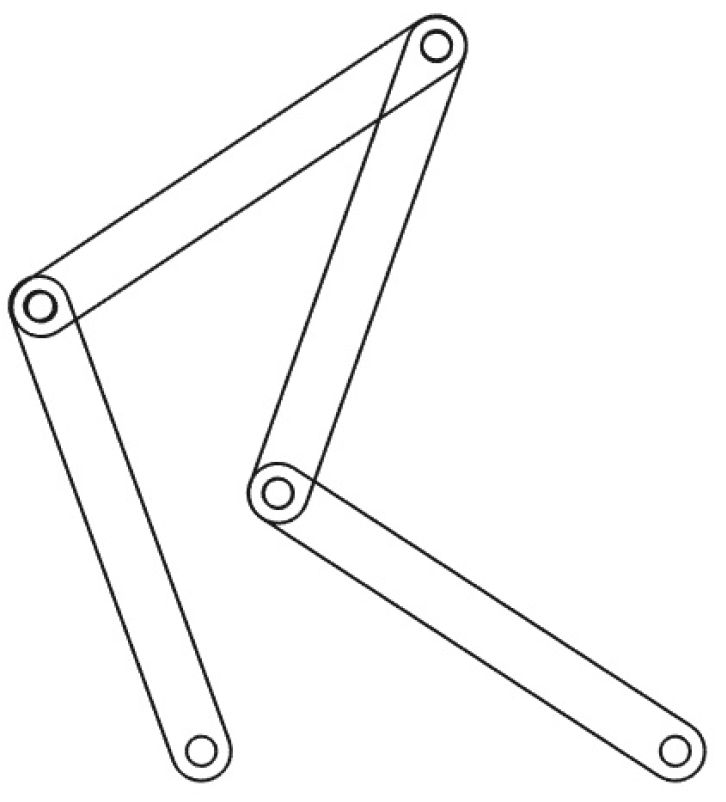         $2\ldotp \;\left(\theta_1^+ ,{\theta_4 }^- \right)$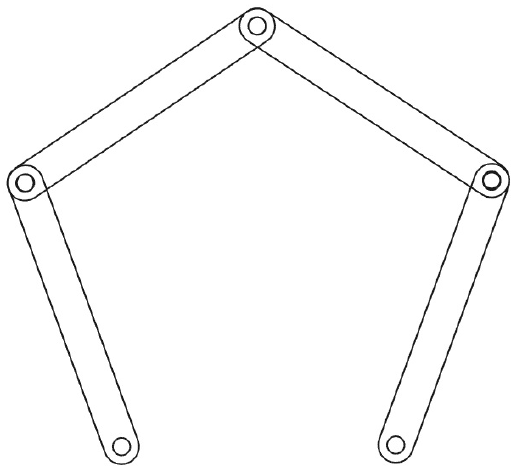

$3\ldotp \;\left(\theta_1^- ,{\theta_4 }^+ \right)$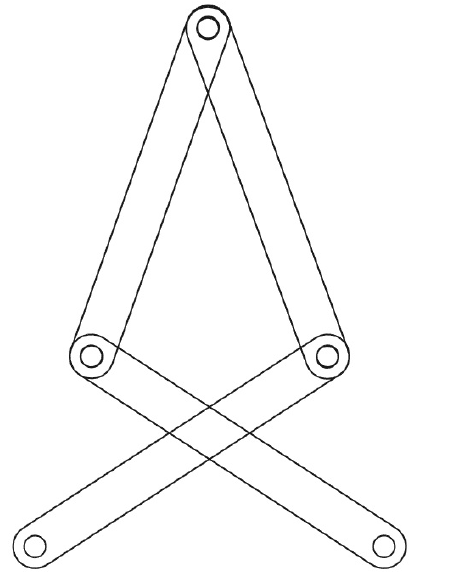             $4\ldotp \;\left(\theta_1^- ,{\theta_4 }^- \right)$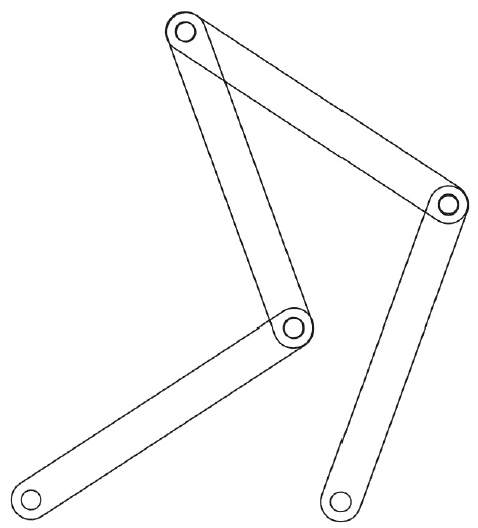

## Singularities

Gosselin and Angeles have proposed a method based on Jacobian matrix for the singularities evaluation of closed-loop mechanism.

Denoting the joint angles $\theta =\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_4 
\end{array}\right\rbrack$and the end-effector pose $x_e =\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$. 


$$\begin{array}{l}
\frac{\partial F}{\partial \theta \;}\dot{\theta \;} +\frac{\partial F}{\partial x_e \;}\dot{x_e } =0\\
J_{\theta \;} \dot{\theta} +J_e \dot{x_e } =0
\end{array}$$


where $F$is a two-dimension implicit function $F\left(\theta ,x_{\textrm{ee}} \right)=0$, describing the relation between the input and the output.


$$F\left(\theta ,x_{\mathrm{ee}} \right)=\left\lbrack \begin{array}{c}
{\left(x-L_A \cos \theta_1 \right)}^2 +{\left(y-L_A \sin \theta_1 \right)}^2 -{L^2 }_B \\
{\left(x-L_C -L_A \cos \theta_4 \right)}^2 +{\left(y-L_A \sin \theta_4 \right)}^2 -{L^2 }_B 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Hence:


$$J_{\theta \;} =2L_A \left\lbrack \begin{array}{cc}
\mathrm{xsin}\theta_1 -\mathrm{ycos}\theta_1  & 0\\
0 & \mathrm{xsin}\theta_4 -L_C \sin \theta_4 -\mathrm{ycos}\theta_4 
\end{array}\right\rbrack$$



$$J_{\textrm{ee}\;} =2\left\lbrack \begin{array}{cc}
x-L_A \cos \theta_1  & y-L_A \sin \theta_1 \\
x-L_C -L_A \cos \theta_1  & y-L_A \sin \theta_4 
\end{array}\right\rbrack$$


Based on the Gosselin and Angeles method, there are three types of singularities:

- ***Type I***: $\det \left\lbrack J_{\theta \;} \right\rbrack =0,\det \left\lbrack J_{\textrm{ee}} \right\rbrack \not= 0\;\to$chain completly folded or extended.

- ***Type II***: $\det \left\lbrack J_{\theta \;} \right\rbrack \not= \;0,\det \left\lbrack J_{\textrm{ee}} \right\rbrack =0\;\to$two passive links are aligned

- ***Type III***: $\det \left\lbrack J_{\theta \;} \right\rbrack =0,\det \left\lbrack J_{\textrm{ee}} \right\rbrack =0\;\to$five joints ($A_1 ,B_1 ,A_2 ,B_2 ,E$) are collinear.

## Trajectory Planning

Trajectory generating = finding the desired joint space trajectory $q\left(t\right)$ given the desired operation (Cartesian) path inverse kinematics.

Denoting with $q$, the vector of the joint parameters $\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_4 
\end{array}\right\rbrack$.


$$x_e \left(t\right)=\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)
\end{array}\right\rbrack ,v_e \left(t\right)=\left\lbrack \begin{array}{c}
v_{e|x} \\
v_{e|y} 
\end{array}\right\rbrack ,a_e \left(t\right)=\left\lbrack \begin{array}{c}
a_{e|x} \\
a_{e|y} 
\end{array}\right\rbrack$$


Joint-space description: the description of the motion to be made by the robot by its joint values. The motion between the two points is unpredictable.

Operational-space description: the description of the motion is in the operational space (cartesian or working space). The motion between two points is known and controllable at all time, but it is difficult to ensure that singuarities does not occur.

Having the path (approximated way points), the trajectory is completed by a choice of a timing law. Considering the path in a parametric form:

- Task Space: ${\mathit{\mathbf{x}}}_{\textrm{ee}} \left(t\right)=\left(x\left(s\right),y\left(s\right)\right)$where the motion law is $s=s\left(t\right),t\in \left\lbrack 0,T\right\rbrack$

- Joint Space: $\mathit{\mathbf{q}}\left(\lambda \right)=\left(q_1 \left(\lambda \right),q_2 \left(\lambda \right)\right)$where the motion law is $\lambda =\lambda \left(t\right)$

The timing law is chosen based on taks specifications (stop in a point, move at a constant velocity, etc.). It could consider optimal criteria and constraints are imposed by actuator capabilities.

#### Trajectory planning in the Task space

- Calculate the path from the initial point to the final point

- Assing a total time $T_{\textrm{path}}$to traverse the path

- Discretize the points in time and space

- Blend a continuous time function between these points

- Solve inverse kinematics at each step

#### Trajectory planning in the Joint space

- Calculate the inverse kinematic solution from the initial point to the final point

- Assign the total time $T_{\textrm{path}}$using maximal velocities in joints

- Discretize the individual joint trajectories in time

- Blend a continuous function between these point

**Summary of Trajectory planning**

A small summary of the pro (OK) and contra (NO) of each space trajectory is herebelow described.


$$\matrix{
\textbf{Operational Space Trajectory} & \textbf{Joint Space Trajectory}                               \cr
\text{OK: Motion is predictable} & \text{NO: Motion not predictable} \cr
\text{OK: Collision-free path obtainable}    & \text{NO: Collision-free path not guaranteed}                             \cr
\text{NO: IK computed each time step}        & \text{OK: IK computed only once}                                     \cr
\text{NO: Unknown how to set total time}    & \text{OK: Joint and velocity constraints} \cr
\text{NO: Actuator motion not always smooth} & \text{OK: Actuator motion smooth} \cr
}$$


## **Simulation**

### **Run FK and IK (first validation): homeConfiguration**

For a first validation, the implemented FK and IK algorithms are run using the `homeConfig` as `desiredPostion` for the end-effector. The FK first shows that exists one solution describing the `homeConfig` end-effector position, for the `homeConfig` joint angles (`th1, th4`). Afterwards the IK checks that, in order to satisfy the desired pose, one possible configuration is given by the initial defined joint angles for the `homeConfig`.

clear solution targetEEPosition; % clear previous solution info to avoid errors or inconsistencies

targetEEPosition.xP = bodyLengths.La*cos(jointAngles.th1) + bodyLengths.Lb*cos(jointAngles.th2);
targetEEPosition.yP = bodyLengths.La*sin(jointAngles.th1) + bodyLengths.Lb*sin(jointAngles.th2);
disp("Desired EE Position: "); disp(targetEEPosition);

Desired EE Position: 
    xP: 21.3900
    yP: 65.8317




solution = FBR.solveFK(bodyLengths.La, bodyLengths.Lb, bodyLengths.Lc, jointAngles.th1, jointAngles.th4);
disp("Solution FK:"); disp(solution);

Solution FK:
     xPp: 21.3900
     yPp: 15.5407
    th2p: -0.6283
    th3p: 3.7699
     xPm: 21.3900
     yPm: 65.8317
    th2m: 0.6283
    th3m: -3.7699




solution = FBR.solveIK(bodyLengths.La, bodyLengths.Lb, bodyLengths.Lc, targetEEPosition.xP, targetEEPosition.yP);
disp("Solution IK:"); disp(solution);

Solution IK:
    th1p: 1.8850
    th2p: 0.6283
    th3p: 1.2566
    th4p: 2.5133
    th1m: 0.6283
    th2m: 1.2566
    th3m: 2.5133
    th4m: 1.2566




FBR.searchConfiguration(solution, jointAngles);

th1=theta1p -> 108.0 (rad=1.8850)
th4=theta4m -> 72.0 (rad=1.2566)


### Run IK (second validation): RigidBody test

The inverse kinematic solution is compared with the one calculated using the Matlab `generalizedInverseKinematics` for a `RigidBody`.

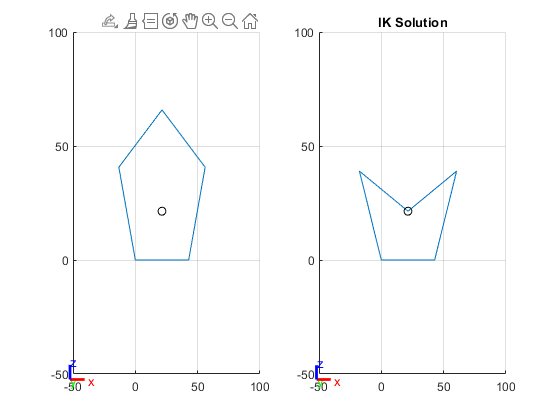

clear solution targetEEPosition; % clear previous solution info to avoid errors or inconsistencies

targetEEPosition.xP = bodyLengths.Lc/2;
targetEEPosition.yP = bodyLengths.Lc/2;

% solve IK using rigidBody IK
waypoint = [targetEEPosition.xP -0.1 targetEEPosition.yP];
solution_rigidBody = FBR.RigidBody.solveIK(fbrRigidBody, qInitRigidBody, waypoint, true);


solution = FBR.solveIK(bodyLengths.La, bodyLengths.Lb, bodyLengths.Lc, targetEEPosition.xP, targetEEPosition.yP);
disp("Solution IK:"); disp(solution);

Solution IK:
    th1p: 1.9948
    th2p: -0.4240
    th3p: 1.1468
    th4p: -2.7176
    th1m: -0.4240
    th2m: 1.1468
    th3m: 2.7176
    th4m: 1.1468




solutionFound = FBR.searchConfiguration(solution, solution_rigidBody);

th1=theta1p -> 114.3 (rad=1.9948)
th4=theta4m -> 65.7 (rad=1.1468)


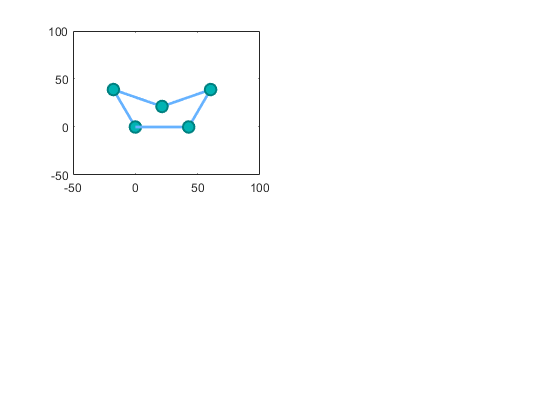

Unrecognized function or variable 'llConfigurations'.


allConfigurations = FBR.getAllConfigurations(solution);

% plot all the configurations
figure;
for i=1:size(allConfigurations)
    subplot(2, 2, i);
    FBR.plotConfiguration(bodyLengths, allConfigurations(i, :), [], targetEEPosition);
    title(sprintf('Configuration (%s, %s)', ...
        utils.getAngleSign(llConfigurations(i, :).th1), ...
        utils.getAngleSign(llConfigurations(i, :).th4)));
end

### Trajectory Planning: task space trajectory

Generates cartesian (operational) space trajectories by performing inverse kinematics after genering the trajectory.

clear solutionTS;

startTrajctory.withRigidBody       = false;
startTrajctory.withoutRigidBody    = true;

trajectoryType = "cubic";

dim = 10;
%waypoints = [ones(1, dim)*bodyLengths.Lc/2; ones(1, dim)*-0.1; linspace(bodyLengths.Lc/2+50, bodyLengths.Lc/2+5, dim)];
x = linspace(bodyLengths.Lc/2-5, bodyLengths.Lc/2+5, dim);
y = ones(1, dim)*-0.1;
z = linspace(bodyLengths.Lc/2+50, bodyLengths.Lc/2+5, dim);
fullWaypoints = [x; y; z];
waypoints = fullWaypoints([1, 3], :);
waypointVels = 0.1 *[0  1; -1  0; 0 -1; 1  0; 0  1; 0  1; -1  0; 0 -1; 1  0; 0  1]'; % Velocity (cubic and quintic)
waypointTimes = 0:size(waypoints, 2)-1;
if startTrajctory.withRigidBody
    figure;
    set(gcf,'Visible','on'); % plot figure externally in order to see real time plot.
    [solutionTS, ~, execTime] = FBR.RigidBody.TrajectoryPlanning.taskSpace(fbrRigidBody, fullWaypoints, trajectoryType);
    disp('Time: '); disp(execTime);
end
if startTrajctory.withoutRigidBody
    figure;
    set(gcf,'Visible','on'); % plot figure externally in order to see real time plot.
    [solutionTS, ~, execTime] = FBR.trajectoryPlanningTaskSpace(bodyLengths, waypoints, trajectoryType);
    disp('Time: '); disp(execTime);
end

### Trajectory Planning: joint space trajectory

Generates Joint space trajectories by performing inverse kinematics on each waypoint and interpolating between the joint angles.

clear solutionJS;

startTrajctory.withRigidBody       = false;
startTrajctory.withoutRigidBody    = true;

dim = 5;
fullWaypoints = [ones(1, dim)*bodyLengths.Lc/2; ones(1, dim)*-0.1; linspace(bodyLengths.Lc/2+50, bodyLengths.Lc/2+5, dim)];
waypoints = fullWaypoints([1, 3], :);
waypointVels = 0.1 *[0  1; -1  0; 0 -1; 1  0; 0  1]'; % Velocity (cubic and quintic)
waypointTimes = 0:size(waypoints, 2)-1;
if startTrajctory.withRigidBody
    figure;
    set(gcf,'Visible','on'); % plot figure externally in order to see real time plot.
    [solutionJS, ~, execTime] = FBR.RigidBody.TrajectoryPlanning.jointSpace(fbrRigidBody, fullWaypoints);
    disp('Time: '); disp(execTime);
end
if startTrajctory.withoutRigidBody
    figure;
    set(gcf,'Visible','on'); % plot figure externally in order to see real time plot.
    [solutionJS, ~, execTime] = FBR.trajectoryPlannigJointSpace(bodyLengths, waypoints);
    disp('Time: '); disp(execTime);
end

Generating waypoints...
Generating trajectory (input=trap)...


### Simulate Model

Mode = "TaskSpace";

switch Mode
    case "TaskSpace"
        TP_MODE = 1
    case "JointSpace"
        TP_MODE = 2
end
open_system("FBRModel.slx");
sim("FBRModel");